clear all
clf
format shortg

N = 4; % number of members
T = 10000/N *1.2; %Nm %with a safty factor for multigrib
R = 0.10; %m biggeste shaft with a sleve 
F_n = T/R % the force to over come from the torque

F_n =        30000


theta = 30;
mu_s = 0.2; %frictions coefficenten for stål imod stål
syms F_n_rail F_tight

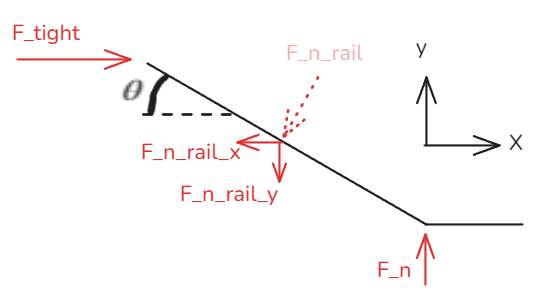

F_n_rail_x = F_n_rail * sind(theta); %normal force in x direction of the rail

F_n_rail_y = F_n_rail * cosd(theta); % normal force in y dircetion of the rail

eq_x = 0 == F_tight - F_n_rail_x; % x equation
eq_y = 0 == F_n_rail_y - F_n;  % y equation

[sol_F_n_rail, sol_F_tight] = solve([eq_x, eq_y], F_n_rail, F_tight);
F_n_rail = double(vpa(sol_F_n_rail,5)) % forces on member

F_n_rail =         34641


F_tight =  double(vpa(sol_F_tight,5)) % tightning force on on the members

F_tight =         17321



S_y = 370; %MPa
A_required = F_n_rail/S_y % Needed area to take the force before yeilding.

A_required =        93.624



Travel_y = tand(theta)

Travel_y =       0.57735



l = 0.2; %x length of member
A_section_member = 20*20 %mm^2 %member is 20mmx20mm

A_section_member =    400


S = T/l / A_section_member

S =          37.5


Creating a graph for diffrent angles

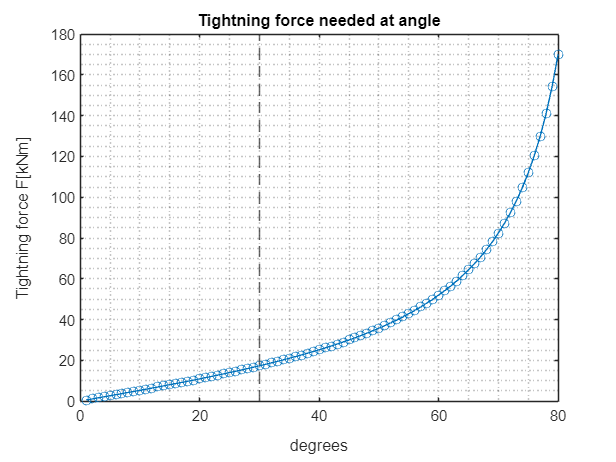

theta_lin = 1:1:89;
syms F_n_rail F_tight

for i=theta_lin
    F_n_rail_x = F_n_rail * sind(i);
    F_n_rail_y = F_n_rail * cosd(i);
    
    eq_x = 0 == F_tight - F_n_rail_x;
    eq_y = 0 == F_n_rail_y - F_n;

    [sol_F_n_rail, sol_F_tight] = solve([eq_x, eq_y], F_n_rail, F_tight);
    F_n_rails(i) = double(vpa(sol_F_n_rail,5));
    F_tights(i) = double(vpa(sol_F_tight,5));
    length(F_tights);

    thetas(i) = i;
end
plot(thetas, F_tights/1e3, '-o')
title("Tightning force needed at angle")
xline(theta,'--')
hold on
grid("minor")
xlabel("degrees")
ylabel("Tightning force F[kNm]")
xlim([0,80])
hold off

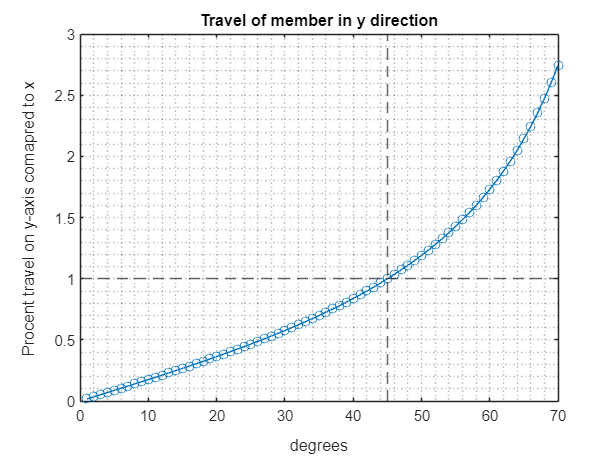


for i=theta_lin
    Travel_ys(i) = tand(i);
    thetas(i) = i;
end
plot(thetas, Travel_ys, '-o')
title("Travel of member in y direction")
grid("minor")
xlabel("degrees")
xline(45,'--')
yline(1,'--')
xlim([0,70])
ylabel("Procent travel on y-axis comapred to x")